IDs and pores

poreID = fopen('PhaseID_pore_2M.bin');
A = fread(poreID);
pores_2M = ismember(A, 0);
find(pores_2M)

ans =         9205
       10736
       12266
       13796
       13797
       15326
       15327
       15328
       16856
       16857


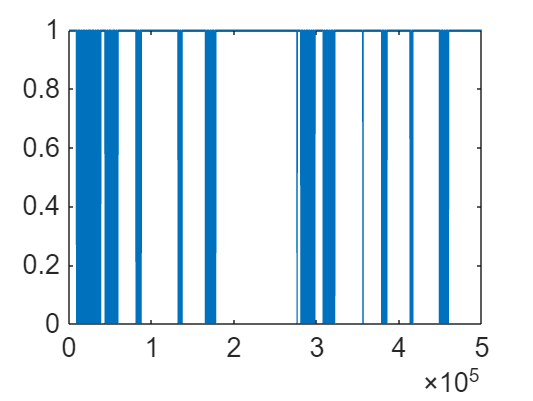

plot(A)
xlim([0 500000])

phaseID = fopen('PhaseID_full.bin');
B = fread(phaseID, 'int');
phasetemp = reshape(B, [], 1301)

phasetemp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

nonAust = ismember(B, 0);
nAinx = find(nonAust);
phasesec = B(1:5000)

phasesec =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


flabel = fopen('porelabel_300M.bin');
C = fread(flabel, 'int');
% PoreLabel = ismember(C, 0);
% find(PoreLabel);
% pores = ismember(C, 1);
% find(pores)
unique(C)

ans =      0
   494
   497
   542
   565
   566
   577
   608
   613
   618


3D to 1D vector confirmation

lim = 1531*1301;
Ctemp = C(1:lim);
x = reshape(Ctemp, 1531, [])

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i=2:25
    Ctemp = C(1+lim*(i-1):i*lim);
    newOrder = reshape(Ctemp, 1531, []);
    x = cat(3,x,newOrder);
end

x(1:50,1:50,6)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

flabels = fopen('labels_2M.bin');
D = fread(flabels,'int');
labeltemp = reshape(D, [], 1301)

labeltemp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1    61    61    62     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2    76    76    76    76    76    76    76    76    76    76    76    76
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    61    61     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2    76    76    76    76    76    76    76    76    76    76    76    76
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    61    62     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2    76    76    76    76    76    76    76    76    76    76    76    76
     1     1     1     1     1     1     1     1     1     1     1     1     1     2 

labels = ismember(D, 0);
find(labels)


ans =

  0×1 empty double column vector



ROTATIONS

feuler = fopen('eulers_2M.bin');
ROtemp = fread(feuler,inf,'float','l')

ROtemp =     0.4221
    1.2024
    4.5435
    6.2722
    2.7384
    1.1764
    6.2345
    2.7797
    2.7023
    6.2345


ROT = reshape(ROtemp, 3, []).'

ROT =     0.4221    1.2024    4.5435
    6.2722    2.7384    1.1764
    6.2345    2.7797    2.7023
    6.2345    2.7797    2.7023
    6.2038    2.7791    2.6699
    6.2038    2.7791    2.6699
    4.7192    2.3384    6.2169
    4.7192    2.3384    6.2169
    4.7227    2.3393    6.2207
    4.7078    2.3448    6.2154


rot = rotation.byEuler(ROT)

 
rot = rotation
  size: 2000001 x 1
 
  show Euler angles
 


rotsec = rot(1:5000)

 
rotsec = rotation
  size: 5000 x 1
 
  show Euler angles
 


% rot = rotation.byEuler(ROT(:,1),ROT(:,2),ROT(:,3))


Orientations

ori = orientation.byEuler(ROT(1:1991831,1:3));

Self orientations

ORItrial = [1 2 2; 1 3 1; 1 3 1; 1 2 0; 5 1 0; 1 2 3; 1 2 2]

ORItrial =      1     2     2
     1     3     1
     1     3     1
     1     2     0
     5     1     0
     1     2     3
     1     2     2


xddd = orientation.byEuler(ORItrial)

 
xddd = orientation (1 → xyz)
  size: 7 x 1
 
  Bunge Euler angles in degree
     phi1     Phi    phi2
  57.2958 114.592 114.592
  57.2958 171.887 57.2958
  57.2958 171.887 57.2958
  57.2958 114.592       0
  286.479 57.2958       0
  57.2958 114.592 171.887
  57.2958 114.592 114.592
 


store = xddd(2:4)

 
store = orientation (1 → xyz)
  size: 3 x 1
 
  Bunge Euler angles in degree
     phi1     Phi    phi2
  57.2958 171.887 57.2958
  57.2958 171.887 57.2958
  57.2958 114.592       0
 


xddd(2:4) = repmat(xddd(1),1,3)

 
xddd = orientation (1 → xyz)
  size: 7 x 1
 
  Bunge Euler angles in degree
     phi1     Phi    phi2
  57.2958 114.592 114.592
  57.2958 114.592 114.592
  57.2958 114.592 114.592
  57.2958 114.592 114.592
  286.479 57.2958       0
  57.2958 114.592 171.887
  57.2958 114.592 114.592
 


Properties

fbse = fopen('BSE_2M.bin');
bsetemp = fread(fbse,inf,'float','l');
bse = reshape(bsetemp, [], 1301)

bse =     0.5317    0.3125    0.5952    0.6932    1.1739    0.7225    0.8130    0.3905    0.3310    0.2620    0.3375    0.8521    0.7995    0.8740    0.7160    0.5212    0.8383    1.0356    0.8119    0.8538    1.2495    1.6443    0.6642    0.1029   -0.3803   -0.7507   -1.0733   -1.1618   -0.7874   -0.0745   -0.0430    0.1885    0.5142    0.7356    0.9683    1.1135    1.3316    1.4801    1.3871    1.2488    1.7256    1.6574    1.0511    0.6134   -0.4164   -0.4916   -1.0212   -0.7247   -1.1791   -1.2187
   -2.5388   -1.8637    0.7726    1.2937    1.0842    0.7859    0.9403    0.4770    0.3668    0.3538    0.4057    0.6180    0.5816    0.8985    0.5732    0.7456    0.6614    0.9097    0.3496    0.8765    1.4006    1.5711    0.4934   -0.3128   -0.7260   -0.8950   -1.3930   -1.3224   -0.6564   -0.0348    0.4247    0.5654    0.4190    0.6903    0.8642    1.2063    1.3360    1.4614    1.3741    1.2809    1.6691    1.4150    1.3036    0.7167   -0.4482   -0.7053   -1.2096   -1.1707   -1.2344   


fci = fopen('CI_2M.bin');
citemp = fread(fci,inf,'float','l');
ci = reshape(citemp, [], 1301)

ci =     0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880
    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9520    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    


ffit = fopen('Fit_2M.bin');
fittemp = fread(ffit,inf,'float','l');
fit = reshape(fittemp, [], 1301)

fit =     0.6720    1.1240    1.1240    1.3970    1.5870    1.4900    1.4450    2.0660    2.0520    1.5260    1.7530    2.1760    1.6020    2.0730    2.0730    2.2610    2.3510    2.2230    1.5650    1.3020    1.6850    1.7390    1.7970    1.1860    0.9080    0.6770    0.6360    0.5430    0.5430    0.8090    0.6730    0.9540    0.5360    0.4900    0.7820    0.7730    1.3480    1.7960    1.3350    0.7510    0.7830    0.6430    0.6260    0.6260    0.9140    0.8360    0.5790    0.5360    0.5520    0.6920
    1.0100    0.9470    0.9480    0.9480    0.9840    1.1070    1.5270    1.6500    1.3390    1.3940    2.1950    1.6750    1.8900    2.3220    1.9440    1.9440    1.9180    1.1820    0.9820    1.0760    1.2540    2.0000    1.5810    0.9110    0.9250    0.7380    0.6550    0.5280    0.6120    0.6120    0.6210    0.5610    0.4920    0.5500    0.6020    0.6660    0.8360    1.5570    1.5630    0.8350    0.8870    0.7810    0.5600    0.6420    0.6420    0.7190    0.8610    0.7800    0.6080   


fiq = fopen('IQ_2M.bin');
iqtemp = fread(fiq,inf,'float','l');
iq = reshape(iqtemp, [], 1301)

iq = 1.0e+04 *

    0.6698    0.6712    0.6712    0.6693    0.7062    0.6886    0.6564    0.5994    0.5215    0.4713    0.4656    0.4775    0.4381    0.3633    0.3633    0.3507    0.3666    0.4015    0.4309    0.4634    0.4545    0.5160    0.5637    0.6050    0.6530    0.7748    0.8707    0.9013    0.9013    0.8786    0.8687    0.9017    0.8978    0.8663    0.8337    0.8032    0.7143    0.6766    0.7183    0.8008    0.8922    0.9701    1.0328    1.0328    1.0481    1.0477    1.0137    0.9833    0.9394    0.9367
    0.5613    0.6123    0.6340    0.6340    0.6625    0.6366    0.5651    0.5292    0.4984    0.5182    0.5215    0.4871    0.4221    0.3821    0.4027    0.4027    0.4469    0.5022    0.5542    0.5550    0.5537    0.5447    0.5872    0.6394    0.6887    0.7787    0.8400    0.8607    0.8591    0.8591    0.8719    0.8994    0.9009    0.8756    0.8389    0.8162    0.7155    0.6568    0.6950    0.7633    0.8715    0.9683    1.0367    1.0645    1.0645    1.0509    1.0193    1.0022   

EBSD

prop.ci = citemp(1:1991831);
prop.grainid = D(1:1991831);
prop.iq = iqtemp(1:1991831);
prop.bse = bsetemp(1:1991831);
xtemp = 0:0.75:1147.5;
ytemp = 0:0.75:975;
prop.x = repmat(xtemp,1,1301).';
prop.y = repelem(ytemp, 1531).';
prop.mad = fittemp(1:1991831);
CSList = {'Pore', 'Austenite'};
% rot = rotation.byEuler(phi1,Phi,phi2);

ebsdsec = EBSD(rot(1:1991831),A(1:1991831),CSList,prop)

 
ebsdsec = EBSD
 
 Phase    Orientations    Mineral  Color  Symmetry
     0    2288 (0.11%)       Pore                 
     1  1989543 (100%)  Austenite                 
 
 Properties: ci, grainid, iq, bse, x, y, mad
 Scan unit : um
 


ebsdsec.orientations = orientation.byEuler(ROT(1:1991831, 1:3));
% plot(ebsdsec)

  I'm going to colorize the orientation data with the 
  standard MTEX ipf colorkey. To view the colorkey do:
 
  ipfKey = ipfColorKey(ori_variable_name)
  plot(ipfKey)


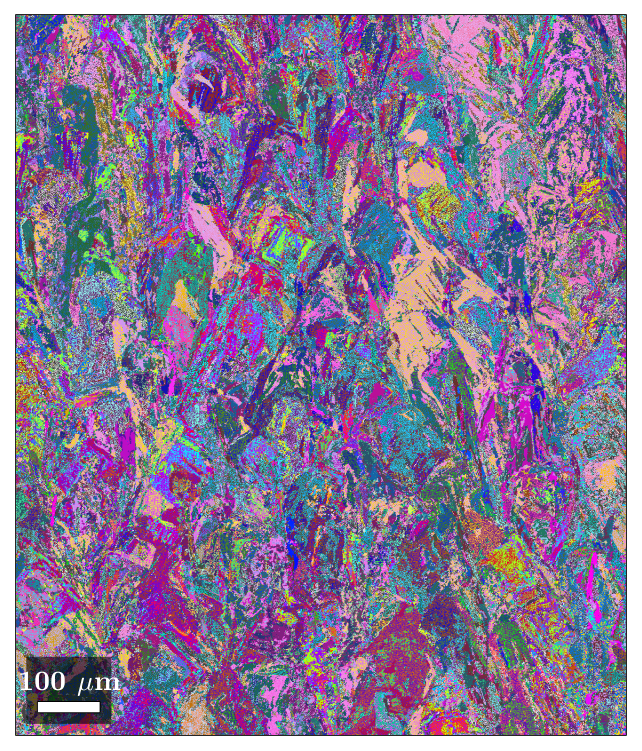

plot(ebsdsec, ebsdsec.orientations)

ori = ebsdsec.orientations;
odf = calcDensity(ori)

 
odf = SO3FunHarmonic (1 → xyz)
  bandwidth: 25
  weight: 1
 


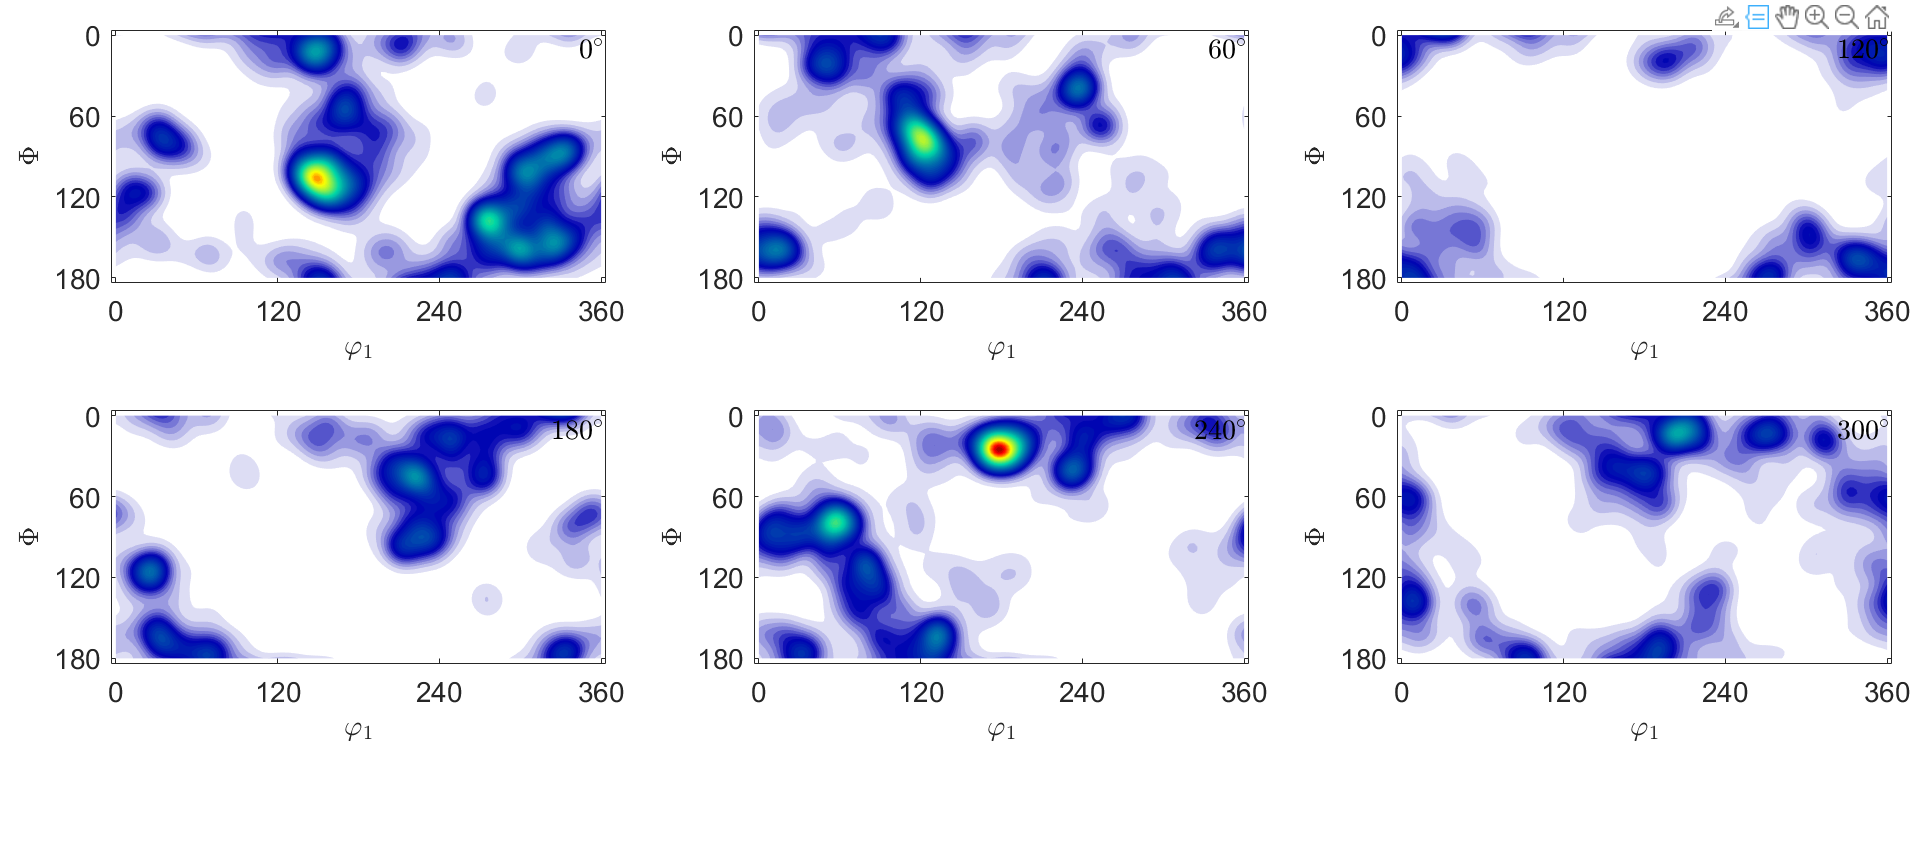

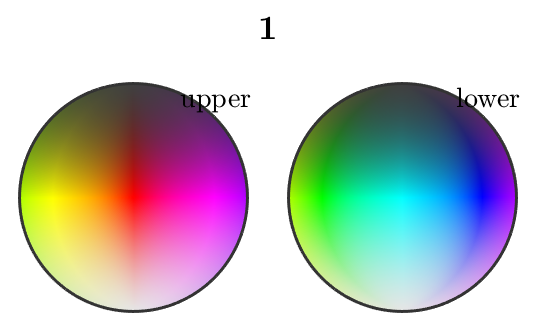

plot(odf)

clear 

A=[1,2,5,2,3,4,2].'

A =      1
     2
     5
     2
     3
     4
     2


sum(A==2)

ans = 3


x = [10 25 4 10 9 4 4]

x =     10    25     4    10     9     4     4


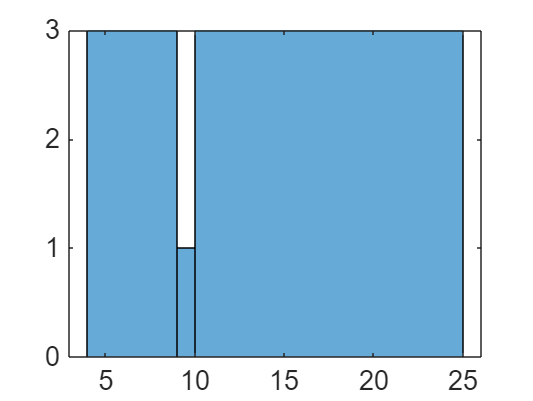

[a,b]=hist(x,unique(x))
histogram(x,unique(x))

TRIALS TEEEEEEMP

X = [1 2 3; 4 0 0; 7 8 0]

X =      1     2     3
     4     0     0
     7     8     0


xd = ismember(X, 0);
find(xd)

ans =      5
     8
     9



Lrow = 0.75*(1-1-1531*floor(1-1/1531))

Lrow = 0

Urow = 0.75*(2000-1531*floor(2000/1531))

Urow = 351.7500



Lrow = 0.75*(Llim/1301);
Urow = 0.75*(Ulim/1301);
Lcol = 0.75*floor(Llim/1531);
Ucol = 0.75*floor(Llim/1531);

% Definir un arreglo bidimensional de ejemplo
A = magic(5)  % Ejemplo de matriz mágica 5x5, puedes usar cualquier matriz que desees

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9



% Especificar la porción que deseas extraer
m = 2;  % Número de filas en la porción
n = 3;  % Número de columnas en la porción
start_row = 2;  % Fila inicial (índice)
start_col = 3;  % Columna inicial (índice)

% Extraer la porción especificada
portion = A(start_row:start_row+m-1, start_col:start_col+n-1);

% Convertir la porción en un arreglo unidimensional
portion_vector = portion(:);

% Mostrar los resultados
disp('Porción extraída:');

Porción extraída:


disp(portion);

     7    14    16
    13    20    22



disp('Arreglo unidimensional:');

Arreglo unidimensional:


disp(portion_vector);

     7
    13
    14
    20
    16
    22

